% Define intial conditions 
AU = 149.6*(1e6); % km 
mu = 132712440041.9394; % km^3/s^2  
kep_Earth = [1.00000011*AU; 0.016710212;deg2rad(0.00005);...
    deg2rad(-11.26064); deg2rad(102.94719); deg2rad(100.46435)];
kep_Didy = [1.6442*AU; 0.38385; deg2rad(3.4079);...
    deg2rad(73.196); deg2rad(319.321); deg2rad(195.0)];
tof_E = 12*86400; % seconds 
tof_D = 412*86400; % sec

% Define initial conditions for rotation of spacecraft 
q0 = [1; 0; 0; 0]; % quarterion  
w0 = [0; 0; 0]; % angular velocity 

% Initial position for Jupiter 
a_jup = 5.20288700 * AU;   % semi-major axis [km]
e_jup = 0.04838624;        % eccentricity
i_jup = deg2rad(1.30440);  % inclination [rad]
Omega_jup = deg2rad(100.4739); % RAAN [rad]
omega_jup = deg2rad(273.8777); % argument of periapsis [rad]
ta_jup    = deg2rad(20.020);   % true anomaly at J2000 [rad]
kep_jupiter = [a_jup; e_jup; i_jup; Omega_jup; omega_jup; ta_jup];
rv_jup = kep2rv(kep_jupiter,mu); 

% Convert Kelperian Elements to rv vectors
rv_Earth = kep2rv(kep_Earth,mu);
rv_Didy = kep2rv(kep_Didy,mu);

% Part A
% Find position vector of Earth after 12 days
rv_E12 = propagate_elliptical(rv_Earth, tof_E, mu);
r_E12 = rv_E12(1:3); % km
v_E12 =  rv_E12(4:6); % km/s 
% Print r_E12 and v_E12 values
fprintf('Earth position after 12 days = [%g, %g, %g] km\n',...
    r_E12(1), r_E12(2), r_E12(3));

Earth position after 12 days = [-1.37632e+08, -6.09102e+07, -75.5878] km


fprintf('Earth velocity after 12 = [%g, %g, %g] km/s\n',...
    v_E12(1), v_E12(2), v_E12(3));

Earth velocity after 12 = [11.5578, -27.2549, -2.13579e-05] km/s


% Part B 
% Find position vector and velocity vector of Didymos after 412 days 
rv_D412 = propagate_elliptical(rv_Didy, tof_D, mu); 
r_D412 = rv_D412(1:3); % km 
v_D412 = rv_D412(4:6); % km/s
fprintf(['Didymos position after 412 days' ...
    ' [%g, %g, %g] km\n'], r_D412(1), r_D412(2), r_D412(3));

Didymos position after 412 days [-9.33545e+07, 1.79932e+08, 8.41945e+06] km


fprintf(['Didymos velocity after 412 days  ' ...
    '    [%g, %g, %g] km/s\n'], v_D412(1), v_D412(2), v_D412(3));

Didymos velocity after 412 days      [-27.4659, -3.47547, 1.50591] km/s



% Create paramaters database
% For Jupiter Perturbations 
params.MUJup = 12686534; % km^3 / s^2 
params.Jup = rv_jup; 
params.MUSun = mu; 

% For SRP 
params.AU = AU;
params.Cr = 1.5; 
params.Psrp = (4.56e-6); % m 
params.Area = 10; % m^2 
params.mass = 500; % kg 

% Define Rotaional Parameters
lx = 1.0;   % m
ly = 1.0;   % m
lz = 2.0;   % m
m  = 500;   % kg
Ixx = (m/12) * (ly^2 + lz^2); % kg*m^2
Iyy = (m/12) * (lx^2 + lz^2); % kg*m^2
Izz = (m/12) * (lx^2 + ly^2); % kg*m^2
params.I = diag([Ixx; Iyy; Izz]);   % 3x3 diagonal matrix
params.r_cp = [-1.5; 0; 0]; % m 

% Calculate delta_V of the transfer 
tol = 1e-8; % tolerance 
tof = tof_D - tof_E; % s 
cw = 0; % anti-clockwise
[v1, v2] = lambert_universal(r_E12,r_D412,tof,mu,cw,eps,1e-8);
v1;
deltav = norm(v_E12 - v1) + norm(v2 - v_D412);
fprintf('The total transfer is %g km/s ', deltav)

The total transfer is 20.0279 km/s 


% New velocity results from third body perturbations 
v1_true = correct_lambert(r_E12, r_D412, tof, v1, params);

Shooting Iteration 1... Miss Distance: 62247.4437 km
Shooting Iteration 2... Miss Distance: 10.7251 km
Shooting Iteration 3... Miss Distance: 0.0034 km


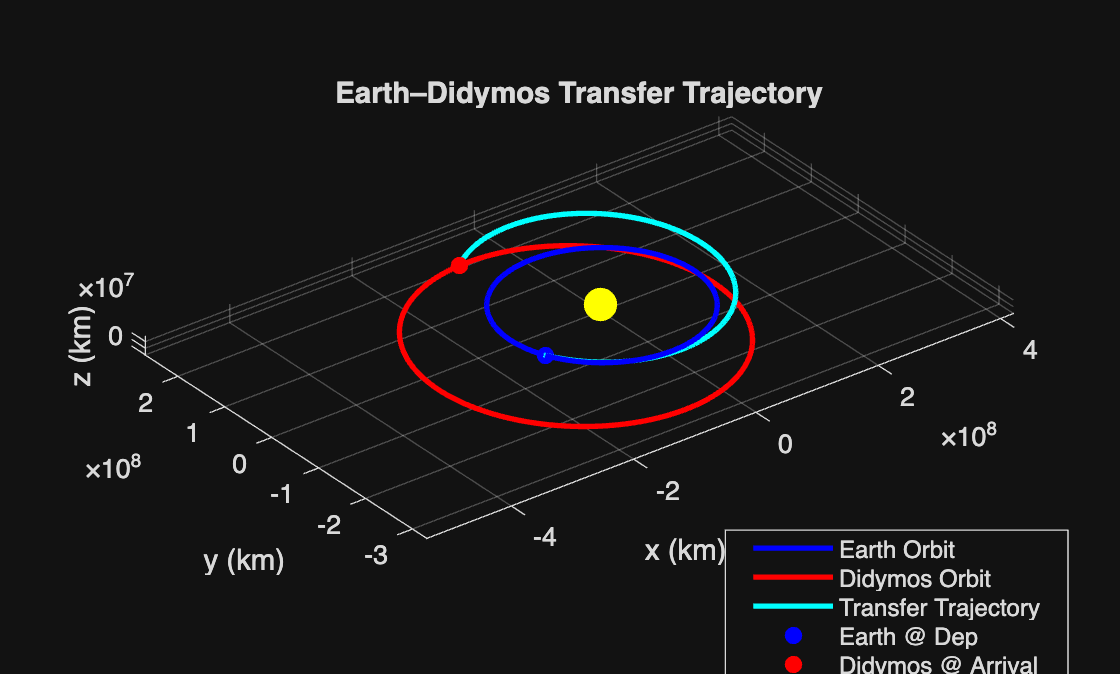

% Plot the figure
% Define Period for Earth and Didymos
T_E = (2*pi)*(sqrt(kep_Earth(1)^3 / mu));
T_D = (2*pi)*(sqrt(kep_Didy(1)^3 / mu));

% Define initial array for the Interplanetary Transfer
x1 = [rv_E12(1:3); v1_true];
x1_r = [q0; w0]; 

% Set Tolerances
opts_t = odeset('RelTol',1e-12,'AbsTol',1e-12);
opts_r = odeset('RelTol',1e-13,'AbsTol',1e-13); 
% Solve ODE For the Orbits 
[tE, xE] = ode78(@(t,x) eom_twobody(t,x,mu), [0,T_E], rv_Earth, opts_t);
[tD, xD] = ode78(@(t,x) eom_twobody(t,x,mu), [0,T_D], rv_Didy, opts_t);
[tH, xH] = ode78(@(t,x) eom_3dof(t,x,params), [0, tof], x1, opts_t);
% Extend params data base for rotation 
params.t_traj = tH;
params.r_traj = xH(:,1:3);

% Plot the Orbits 
figure;
hold on; 
plot3(xE(:,1), xE(:,2), xE(:,3),'b','LineWidth', 2.0)
plot3(xD(:,1), xD(:,2), xD(:,3),'r','LineWidth', 2.0)
plot3(xH(:,1), xH(:,2), xH(:,3),'c', 'LineWidth', 2.0)
axis equal; grid on; 
view(3)
plot3(r_E12(1), r_E12(2), r_E12(3), 'bo', 'MarkerFaceColor', 'b');
plot3(r_D412(1), r_D412(2), r_D412(3), 'ro', 'MarkerFaceColor', 'r');
% Plot the Sun at the origin
plot3(0,0,0,'yo','MarkerSize',12,'MarkerFaceColor','y');
xlabel('x (km)'), ylabel('y (km)'), zlabel('z (km)')
title('Earth–Didymos Transfer Trajectory'),...
legend('Earth Orbit', 'Didymos Orbit', 'Transfer Trajectory', ...
'Earth @ Dep','Didymos @ Arrival ',Location='southeast')
legend(["Earth Orbit", "Didymos Orbit", "Transfer Trajectory", ...
    "Earth @ Dep", "Didymos @ Arrival"], "Location", "none", "Position", ...
    [0.6472 0.0021 0.3063, 0.1959])

% Comparing Results 
v2_true = xH(end,4:6)'

v2_true =   -18.8821
  -15.5070
   -0.2721


v1;
v2;

% Calculate the error in velocity
error_v1 = norm(v1_true - v1);
error_v2 = norm(v2_true - v2);
fprintf('Error in v1: %g km/s\n', error_v1);

Error in v1: 0.000636303 km/s


fprintf('Error in v2: %g km/s\n', error_v2);

Error in v2: 0.000380952 km/s



% Deep Space Simulation 6DOF
% Define inital vectors at 200 days 
r_start = interp1(tH, xH(:,1:3),200*86400)'; % km 
v_start = interp1(tH, xH(:,4:6),200*86400)'; % km 
jup_200 = propagate_elliptical(rv_jup, 200*86400, mu); % Orbital Elements for Jupiter
params.jup_200 = jup_200;

% For Simulink 
busInfo = Simulink.Bus.createObject(params);
busInfo.busName

ans = 'slBus2'


% Call Simulink model and store vector arrays
simOut = sim('pdcontroller');
r_sim = out.rsim; 
v_sim = out.vsim;
t_out = out.tout; 
r_final = r_sim(:,end)

r_final = 1.0e+08 *

    2.0059
    0.6930
   -0.0074


v_final = r_sim(:,end)

v_final = 1.0e+08 *

    2.0059
    0.6930
   -0.0074


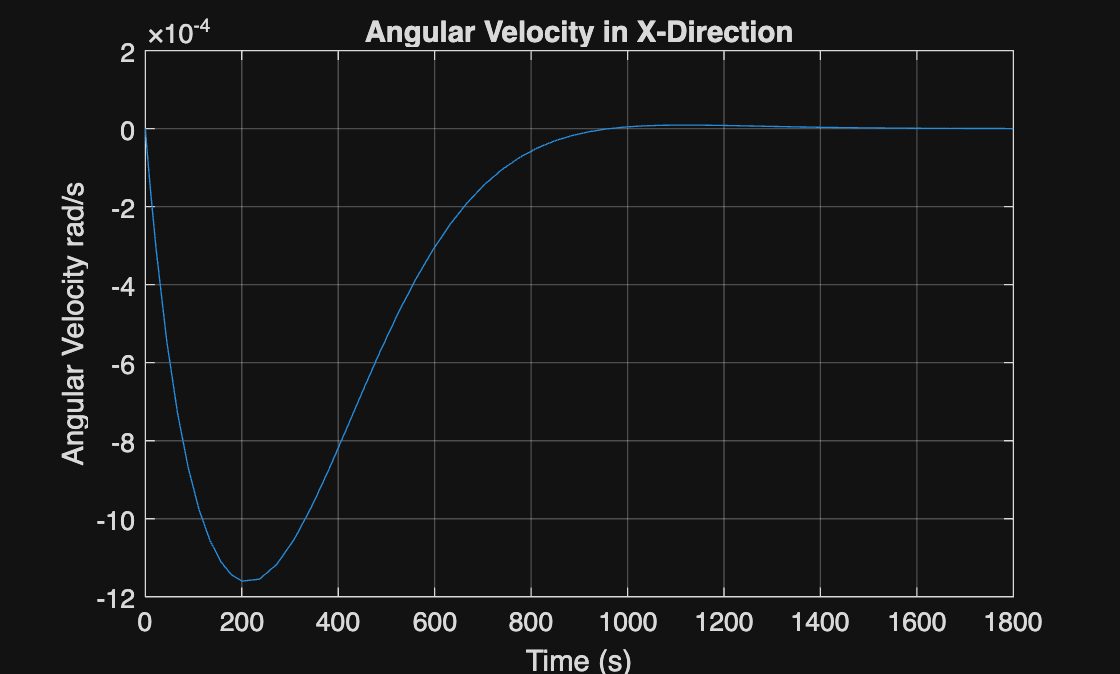

% Extract Angular Velocity
raw_omega = out.angularvelocity.Data; 
w_squeezed = squeeze(raw_omega);
omega = w_squeezed'; 

% Extract Quaternion values
raw_q = out.quaternion.Data; 
q_squeezed = squeeze(raw_q); 
q = q_squeezed';
q_norm = vecnorm(q,2,2); 

% Plot angular velocity results in x-direction 
figure; 
plot(t_out,omega(:,1)), grid on 
xlabel('Time (s)'), ylabel('Angular Velocity rad/s'); 
title('Angular Velocity in X-Direction')

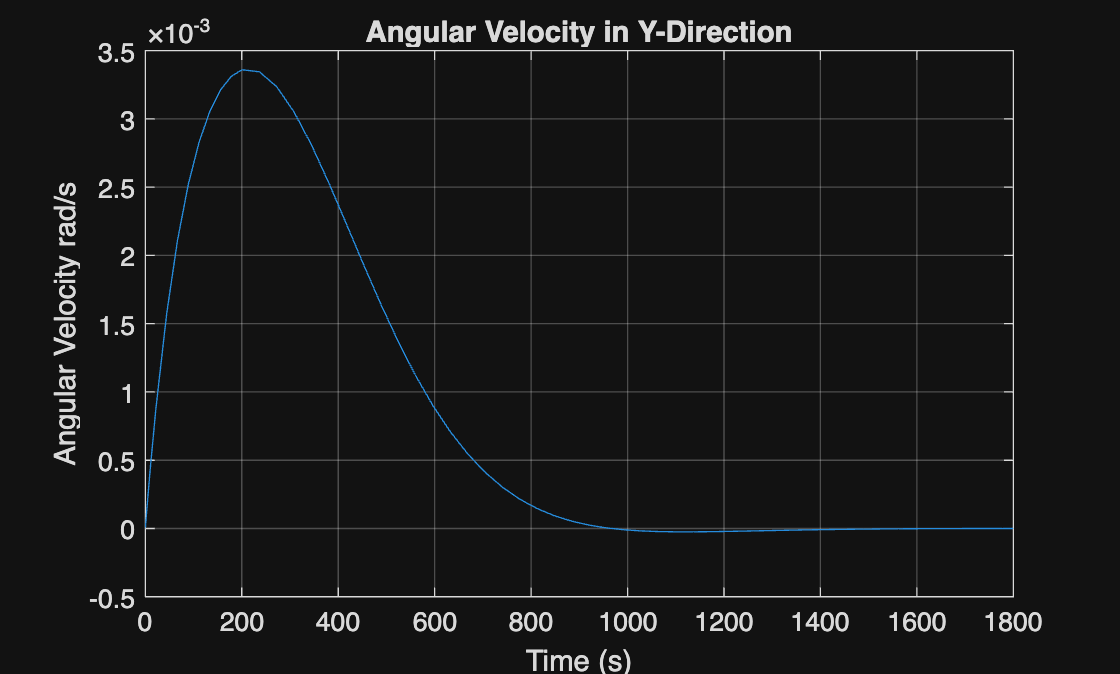


% Plot angular velocity results in y-direction 
figure; 
plot(t_out,omega(:,2)), grid on 
xlabel('Time (s)'), ylabel('Angular Velocity rad/s'); 
title('Angular Velocity in Y-Direction')

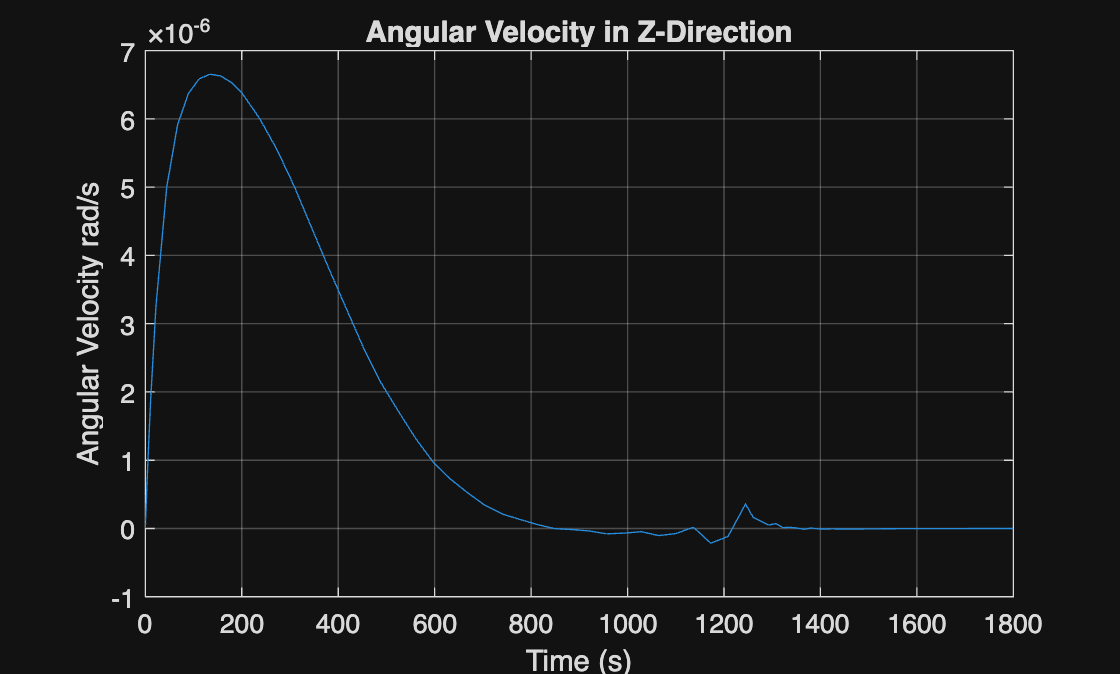


% Plot angular velocity results in z-direction 
figure; 
plot(t_out,omega(:,3)), grid on 
xlabel('Time (s)'), ylabel('Angular Velocity rad/s'); 
title('Angular Velocity in Z-Direction')

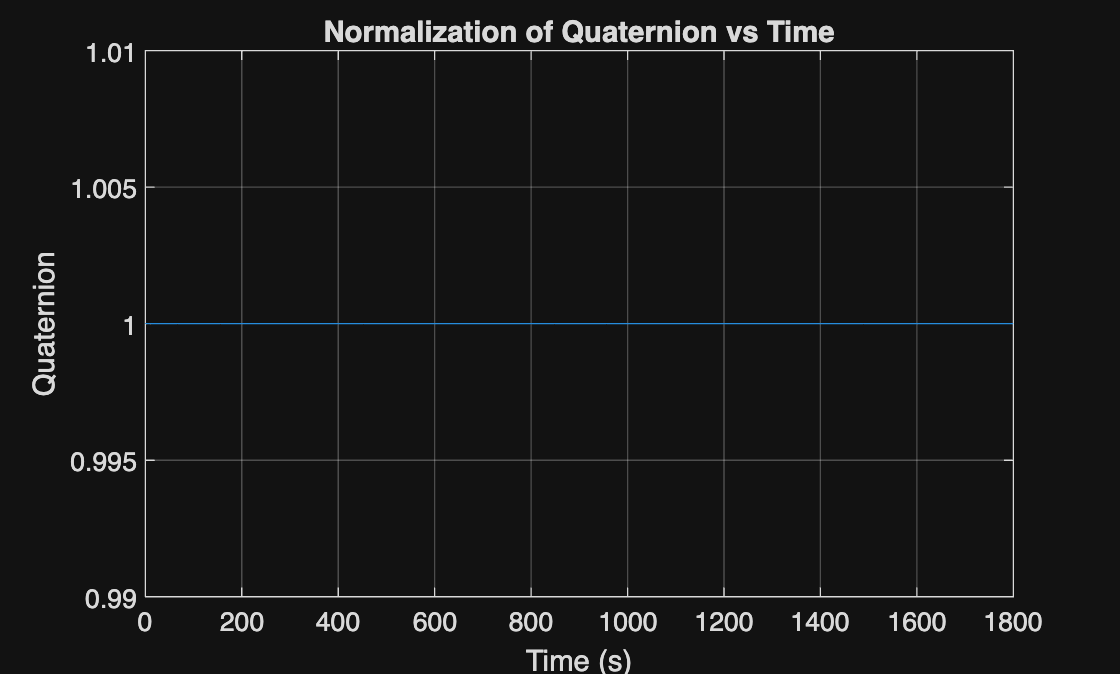


% Plot Quaternion Norm 
figure; 
plot(t_out, q_norm), grid on 
xlabel('Time (s)'), ylabel('Quaternion'); ylim([0.99,1.01])
title('Normalization of Quaternion vs Time')